## Model for Compliant Support of Mating Parts

Reference: Whitney, Daniel E. *Mechanical assemblies: their design, manufacture, and role in product development*. Vol. 1. New York: Oxford university press, 2004.

File: Insertion_model_whitney

Brief: Matlab livescript code for Insertion model based on Whitney Chapter 10 

Author: Mohammad Zaidi Ariffin 

Date: 10 July 2023

Repository: https://github.com/lllllyang/drake-for-Robotic-Insertion

Citation information:

If you use this code or any part of it in your research project, please cite the following publication:

Yang, L.; Ariffin, M.Z.; Lou, B.; Lv, C.; Campolo, D. A Planning Framework for Robotic Insertion Tasks via Hydroelastic Contact Model. *Machines* **2023**, *11*, 741. [https://doi.org/10.3390/machines11070741](https://doi.org/10.3390/machines11070741)

Disclaimer:

This code is provided as-is and without any warranty or guarantee of any kind.

The author shall not be held liable for any direct or indirect damages arising from the use of this code or any part thereof. 

clear all;

**CHAPTER 10**

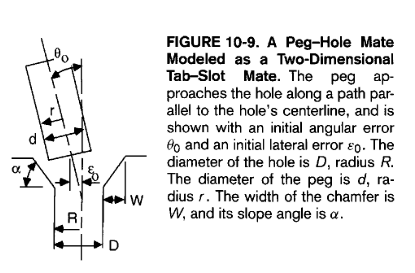

$\epsilon_{0}$ : lateral error

$\theta_{0}
$ : angular error

$D
$ : Diameter of hole

$R$ : Radius of hole

$d$ : Diameter of peg

$r$ : Radius of peg

$W$ : Width of chamfer

$\alpha$ : Slope angle of chamfer

$\delta$ : resulting motion (3 translation and 3 rotations)

$F$ : 6-vector forces and torques (Fx, Fy, Fz, Tx, Ty, Tz)

$C
$: 6 x 6 compliance matrix

$\mu $ : coefficient of friction

Force applied to peg by complainces $F_x$ $F_z$ $M$

Forces applied to peg by contact with hole $f_1$ $f_2$ 

(10-1) $\delta = CF$

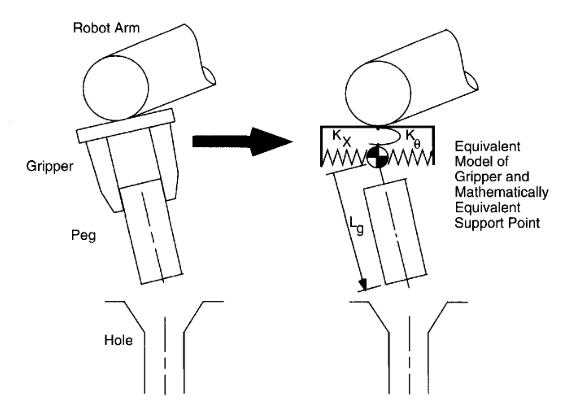

$K_x$ : lateral spring stiffness

$K_\theta$ : angular spring stiffness

$L_g$ : location of compliance centre from tip of the peg

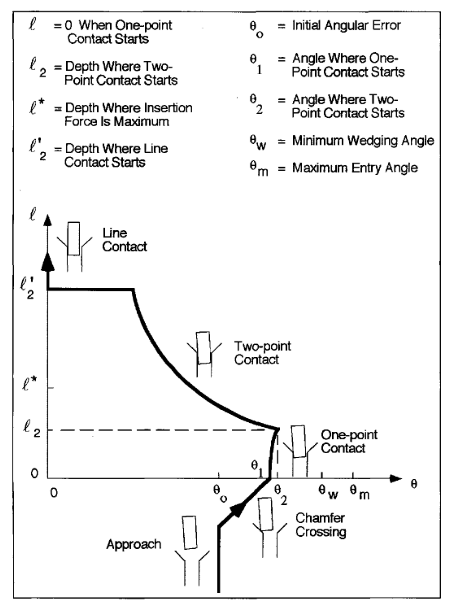

Life cycle of Assembly ( Wobble angle $\theta$ between Peg and hole vs depth of insertion $\ell$)

- Approach

- chamfer crossing z

- one-point contact L = 0

- two-point contact $\ell_2$, $\ell^*$ = max

- line contact $\ell'_2$

*For 2 point contact, the relation of depth, l, to wobble angle, theta:*

(10-2) $\ell\theta = cD$   where (10-3) $c = (D-d)/D$  

$c$ : clearance ratio (describes the different kind of parts)

c = @(D, d) (D-d)/D

c = function_handle with value:
    @(D,d)(D-d)/D


There is a maximum value for $\theta$ which peg cannot even enter hole

(10-4) $\theta_{max} = \sqrt{2c}$

T_max = @(c) sqrt(2*c)

T_max = function_handle with value:
    @(c)sqrt(2*c)


there is a smaller maximum value of $\theta $ that governs -> wedging angle $\theta_w$

**Wedging**

two-point contact - peg is not very far into hole 

largest value of insertion and angle

(10-5) $\ell = \mu d$

(10-6) $\theta_w = c / \mu$ where its valid for $\theta << tan^{-1} (\mu)$

L_maxw = @(mu, d) mu*d

L_maxw = function_handle with value:
    @(mu,d)mu*d


theta_wed = @(c, mu) c/mu

theta_wed = function_handle with value:
    @(c,mu)c/mu


(10-7) $\theta = \theta_0 + S \epsilon_0$ where $S = \frac{K_xL_g}{K_xL_g^2 + K_\theta}$

S = @(K_x, L_g, K_theta) (K_x*L_g)/((K_x*L_g^2) + K_theta)

S = function_handle with value:
    @(K_x,L_g,K_theta)(K_x*L_g)/((K_x*L_g^2)+K_theta)


theta = @(theta_0, S, ep_0) theta_0 + (S*ep_0)

theta = function_handle with value:
    @(theta_0,S,ep_0)theta_0+(S*ep_0)


To cross the chamfer and enter hole:

(10-8) $|\epsilon_0| < W$ &

(10-9) $|\theta_0 + S \epsilon_0| <  \pm c/\mu$

ep_0c = @(W) W 

ep_0c = function_handle with value:
    @(W)W


theta_0c = @(c, mu) c/mu - (S*ep_0c)

theta_0c = function_handle with value:
    @(c,mu)c/mu-(S*ep_0c)


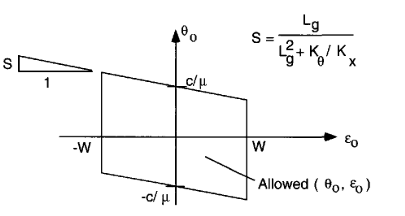

**Jamming**

wrong combination of applied forces acting on peg

dimensionless insertion depth: $\lambda = \ell/\mu D$ (10-10)

lamda = @(l, mu, D) l/(mu*D)

lamda = function_handle with value:
    @(l,mu,D)l/(mu*D)


For cases $K_0 $ is small:

$F_x = -F $ (from deformation of $K_x$)


$$M = L_g F = -L_g F_x$$


(10-11) $\frac{M}{r F_z}  = -\frac{L_g}{r} \frac{F_x}{F_z}$

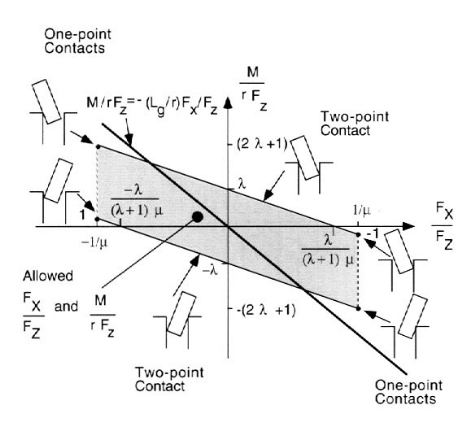

## Part Mating Equations

Chamfer Crossing

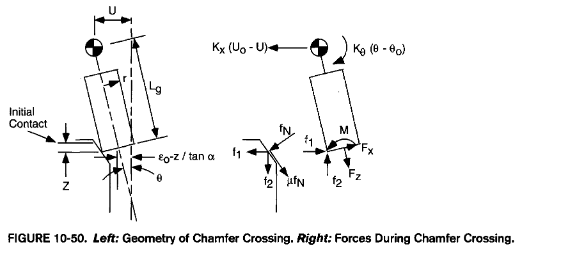

Initial lateral displacement of the support point wrt hole's axis

(10-15) $U_0 = \epsilon_0 + L_g \theta_0$

U_0 = @(ep_0, L_g, theta_0) ep_0 + (L_g*theta_0)

U_0 = function_handle with value:
    @(ep_0,L_g,theta_0)ep_0+(L_g*theta_0)


**Chamfer crossing**

(10-16) $U = L_g\theta - z/ \tan\alpha + \epsilon_0$

ep_0p = @(ep_0, c, R) ep_0 - (c*R)

ep_0p = function_handle with value:
    @(ep_0,c,R)ep_0-(c*R)


z = @(ep_0p,alpha) (ep_0p * tan(alpha)) %trigo based on ep_0 - clearance

z = function_handle with value:
    @(ep_0p,alpha)(ep_0p*tan(alpha))


U_cham = @(L_g, theta, z, alpha, ep_0) L_g*theta - (z/tan(alpha)) + ep_0

U_cham = function_handle with value:
    @(L_g,theta,z,alpha,ep_0)L_g*theta-(z/tan(alpha))+ep_0


$z$ : z starts from the initial contact point (0) to $\epsilon_0' \tan\alpha$ when tip of the peg reaches the bottom of the chamfer and one-point contact begins

To find $U$ & $\theta$ , we have to solve for the forces and moments

Contact forces:

(10-17a) $f_1 = f_N \textbf B$

(10-17b) $f_2 = f_N \textbf A$

where

(10-18) $\textbf A = \cos\alpha+ \mu\sin\alpha$

(10-18) $\textbf B = \sin\alpha- \mu\cos\alpha$

A = @(alpha,mu) cos(alpha) + (mu*sin(alpha))

A = function_handle with value:
    @(alpha,mu)cos(alpha)+(mu*sin(alpha))


B = @(alpha,mu) sin(alpha) - (mu*cos(alpha))

B = function_handle with value:
    @(alpha,mu)sin(alpha)-(mu*cos(alpha))


Compliant support forces:

(10-19) $F_x = -K_x(U_o - U)$

(10-19) $M = K_xL_g(U_0 - U) - K_\theta(\theta - \theta_0)$

Equilibrium of contact forces and compliant support forces assuming $\theta$ is negligibly small:

(10-20) $F_x = -f_1$

(10-20) $F_z = f_2$

(10-20) $M = rf_2$

Combining the above equations yields the expression for $U$ & $\theta$ during chamfer crossing:

(10-21) $\theta = \theta_0 + \frac{K_x(z / \tan\alpha)(L_g \textbf B - r \textbf A)} {(K_xL_g^2 + K_\theta)\textbf B - K_x L_g r \textbf A}$

theta_cross = @(theta_0, K_theta, K_x, z, alpha, L_g, A, B, r) theta_0 + ((K_x * (z/tan(alpha)) * (L_g*B - r*A))/(((K_x*L_g^2 + K_theta)*B)-(K_x*L_g*r*A))) 

theta_cross = function_handle with value:
    @(theta_0,K_theta,K_x,z,alpha,L_g,A,B,r)theta_0+((K_x*(z/tan(alpha))*(L_g*B-r*A))/(((K_x*L_g^2+K_theta)*B)-(K_x*L_g*r*A)))


(10-22) $U = U_0- \frac{K_\theta(z / \tan\alpha) \textbf B} {(K_xL_g^2 + K_\theta)\textbf B - K_x L_g r \textbf A}$

U_cross = @(U_0, K_theta, K_x, z, alpha, L_g, A, B, r) U_0 - ((K_theta * (z/tan(alpha)) * B)/(((K_x*L_g^2 + K_theta)*B)-(K_x*L_g*r*A))) 

U_cross = function_handle with value:
    @(U_0,K_theta,K_x,z,alpha,L_g,A,B,r)U_0-((K_theta*(z/tan(alpha))*B)/(((K_x*L_g^2+K_theta)*B)-(K_x*L_g*r*A)))


**One-Point Contact**

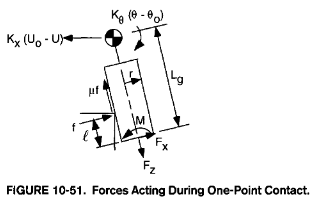

geometric constraint

(10-23) $U = cR + L_g\theta + \ell\theta$

$U$ & $\theta$ during one-point contact:

(10-24) $\theta = \frac{\textbf C(\epsilon'_0 + L_g\theta_0) + K_\theta \theta_0}{\textbf C (L_g - \ell) + K_\theta$

(10-25) $U = U_0 - \frac{K_\theta(\epsilon'_0 + \ell\theta_0)}{\textbf C(L_g - \ell) + K_\theta}$

Where 

(10-26) $\textbf C = K_x(L_g - \ell - \mu r)$

CC = @(K_x, L_g, l, mu, r) K_x*(L_g - l - (mu*r))

CC = function_handle with value:
    @(K_x,L_g,l,mu,r)K_x*(L_g-l-(mu*r))


(10-27) $\epsilon'_0 = \epsilon_0 - cR$

theta_1 = @(ep_0p, C, L_g, theta_0, K_theta, l) (C*(ep_0p + L_g * theta_0) + (K_theta * theta_0))/(C*(L_g - l) + (K_theta))

theta_1 = function_handle with value:
    @(ep_0p,C,L_g,theta_0,K_theta,l)(C*(ep_0p+L_g*theta_0)+(K_theta*theta_0))/(C*(L_g-l)+(K_theta))


U_1 = @(U_0, ep_0p, l, theta_0, C, L_g, K_theta) U_0 - ((K_theta * (ep_0p + (l * theta_0)))/((C*(L_g - l)) + K_theta)) 

U_1 = function_handle with value:
    @(U_0,ep_0p,l,theta_0,C,L_g,K_theta)U_0-((K_theta*(ep_0p+(l*theta_0)))/((C*(L_g-l))+K_theta))


**Two-point contact **

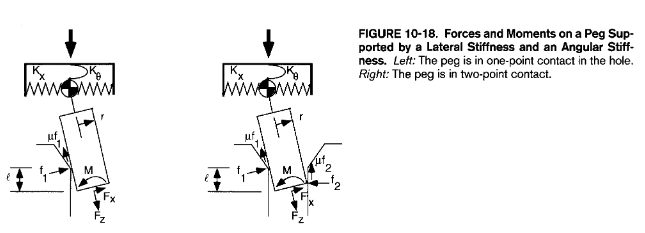

Geometric compatibility

(10-28) $R = \frac{\ell}{2} \tan\theta + r\cos\theta$

Combine (10-15) & (10-23)

(10-29) $U_0 - U = \epsilon' +L_g(\theta_0 - \theta) + \ell\theta$

Sub (10-2) for l where two point contact begins, 

(10-30) $U_0 - U = \epsilon_0'' +L_g(\theta_0 - \theta)$

where (10-31) $\epsilon''_0  =\epsilon_0 + cR$

ep_0pp = @(ep_0, c, R) ep_0 + (c*R)

ep_0pp = function_handle with value:
    @(ep_0,c,R)ep_0+(c*R)


U2 = @(U_0, ep_0pp, L_g, theta_0, theta) U_0 - (ep_0pp + (L_g*(theta_0 - theta)))

U2 = function_handle with value:
    @(U_0,ep_0pp,L_g,theta_0,theta)U_0-(ep_0pp+(L_g*(theta_0-theta)))


From Whitney (Whitney, D. E. (1982). Quasi-static assembly of compliantly supported rigid parts. *Journal of Dynamic Systems, Measurement and Control, Transactions of the ASME*, *104*(1), 65–77. https://doi.org/10.1115/1.3149634), 

A force balance yields for U and theta at onset of two point contact: 

(W-19) $\theta_2 =  \theta_0 + \frac{K_x \epsilon_0''(L_g - l_2 -  \mu r)}{K_xL_g^2 + K_\theta - K_xL_g(l_2 + \mu r)}$

(W-20) $U_2 =  U_0 + \frac{K_x \epsilon_0''}{K_xL_g^2 + K_\theta - K_xL_g(l_2 + \mu r)}$

Substitute (10-2) into W-19

(W-21) $\alpha l_2^2 - \beta l_2 +\gamma = 0$

where 

(W-22)


$$\alpha = K_x(\epsilon_0'' + L_g\theta_0)$$



$$\beta = (L_g - \mu r)\alpha + K_xL_gcD + K_\theta \theta_0$$



$$\gamma = cD(K_xL_g^2 + K_\theta - K_xL_g \mu r)$$


where:

start of 2 point contact - $l_2 = (\beta - \sqrt{\beta^2 - 4\alpha\gamma})/2\alpha$ 

end of 2 point contact (L4 in code)  - $l_2' = (\beta + \sqrt{\beta^2 - 4\alpha\gamma})/2\alpha$

*if L_g & theta_0 are small (beta^2 < 4*alpa*gamma), there will be no 2-point contact*

U0 = @(ep_0, C, D)ep_0 + (C * D/2) % ep_0''

U0 = function_handle with value:
    @(ep_0,C,D)ep_0+(C*D/2)


AA = @(K_x, L_g) (K_x * L_g^2) + K_theta %intermediate step

AA = function_handle with value:
    @(K_x,L_g)(K_x*L_g^2)+K_theta


AL = @(K_x, U0, L_g, theta_0) K_x * (U0 + (L_g *theta_0)) %alpha

AL = function_handle with value:
    @(K_x,U0,L_g,theta_0)K_x*(U0+(L_g*theta_0))


BE = @(AL, L_g, K_x, C, D, mu, K_theta, theta_0) (AL * L_g) + (K_x * L_g * C * D) - (AL * mu * D / 2) + (K_theta * theta_0) %beta

BE = function_handle with value:
    @(AL,L_g,K_x,C,D,mu,K_theta,theta_0)(AL*L_g)+(K_x*L_g*C*D)-(AL*mu*D/2)+(K_theta*theta_0)


GA = @(AA, K_x, L_g, mu, D, C) (AA - (K_x * L_g * mu * D / 2)) * C *D %gamma

GA = function_handle with value:
    @(AA,K_x,L_g,mu,D,C)(AA-(K_x*L_g*mu*D/2))*C*D



L2 = @(BE, AL, GA) (BE - sqrt(BE^2 - (4 * AL * GA)))/ (2 * AL)

L2 = function_handle with value:
    @(BE,AL,GA)(BE-sqrt(BE^2-(4*AL*GA)))/(2*AL)


L4 = @(BE, AL, GA) (BE + sqrt(BE^2 - (4 * AL * GA)))/ (2 * AL)

L4 = function_handle with value:
    @(BE,AL,GA)(BE+sqrt(BE^2-(4*AL*GA)))/(2*AL)


theta_L2 = @(L2, c, D) c*D/L2

theta_L2 = function_handle with value:
    @(L2,c,D)c*D/L2


theta_L4 = @(L4, c, D) c*D/L4 

theta_L4 = function_handle with value:
    @(L4,c,D)c*D/L4


simplified for $K_\theta \gg K_xL_g^2$ & $K_\theta \theta_0 \gg \mu K_x \epsilon''_0 r$

(10-32) $\ell_2 = \frac{cD}{\theta_0}$ - onset

(10-33) $\ell'_2 \cong \frac{K_\theta \theta_0}{K_x \epsilon''_0} - \ell_2$ - termination of two-point

l_2 = @(c, D, theta_0) c*D / theta_0

l_2 = function_handle with value:
    @(c,D,theta_0)c*D/theta_0


l_2p = @(K_theta, theta_0, K_x, ep_0pp, l_2) (K_theta * theta_0)/(K_x * ep_0pp) - l_2 

l_2p = function_handle with value:
    @(K_theta,theta_0,K_x,ep_0pp,l_2)(K_theta*theta_0)/(K_x*ep_0pp)-l_2



theta_l2 = @(l_2, c, D) c*D/l_2

theta_l2 = function_handle with value:
    @(l_2,c,D)c*D/l_2


theta_l2p = @(l_2p, c, D) c*D/l_2p 

theta_l2p = function_handle with value:
    @(l_2p,c,D)c*D/l_2p


From (10-2),

c = @(D, d) (D-d)/D

c = function_handle with value:
    @(D,d)(D-d)/D


theta_2 = @(l, c, D) c*D/l

theta_2 = function_handle with value:
    @(l,c,D)c*D/l


U_2 = @(U_0, ep_0pp, L_g, theta_0, theta_2) U_0 - (ep_0pp + (L_g*(theta_0 - theta_2)))

U_2 = function_handle with value:
    @(U_0,ep_0pp,L_g,theta_0,theta_2)U_0-(ep_0pp+(L_g*(theta_0-theta_2)))


### **Insertion forces**

*lateral force and moment can be obtained analogously*

**Chamfer crossing:**

From equation (10-21) & (10-22) into (10-19) & (10-20)

(10-34) $F_z = \frac{K_x K_\theta \textbf A(z / \tan\alpha)}{\textbf B \textbf D - \textbf E}$

(10-35) $\textbf D = K_xL_g^2 + K_\theta$

(10-36) $\textbf E = K_x L_g r \textbf A$

DD = @(K_x, L_g, K_theta) K_x * L_g^2 + K_theta

DD = function_handle with value:
    @(K_x,L_g,K_theta)K_x*L_g^2+K_theta


E = @(K_x, L_g, r, A) K_x * L_g * r * A

E = function_handle with value:
    @(K_x,L_g,r,A)K_x*L_g*r*A



F_z_c = @(K_x, K_theta, A, z, alpha, B, DD, E) (K_x * K_theta * A * (z/tan(alpha)))/(B*DD - E) 

F_z_c = function_handle with value:
    @(K_x,K_theta,A,z,alpha,B,DD,E)(K_x*K_theta*A*(z/tan(alpha)))/(B*DD-E)


(10-19) $F_x = -K_x(U_o - U)$

(10-22) $U = U_0 - \frac{K_\theta(z / \tan\alpha) \textbf B} {(K_xL_g^2 + K_\theta)\textbf B - K_x L_g r \textbf A}$

F_x_c = @(K_theta, K_x, z, alpha, L_g, A, B, r) -K_x* (((K_theta * (z/tan(alpha)) * B)/(((K_x*L_g^2 + K_theta)*B)-(K_x*L_g*r*A))))

F_x_c = function_handle with value:
    @(K_theta,K_x,z,alpha,L_g,A,B,r)-K_x*(((K_theta*(z/tan(alpha))*B)/(((K_x*L_g^2+K_theta)*B)-(K_x*L_g*r*A))))


**One-point contact:**

From equation (10-24) & (10-25) into (10-19) & (10-20)

(10-37) $F_z = \frac{\mu K_x K_\theta (\epsilon'_0 + \ell \theta_0)}{\textbf C (L_g - \ell) + K_\theta}$

F_z_1 = @(mu, K_x, K_theta, ep_0p, l, theta_0, C, L_g) (mu* K_x * K_theta*(ep_0p + (l * theta_0)))/((C*(L_g - l)) + K_theta)

F_z_1 = function_handle with value:
    @(mu,K_x,K_theta,ep_0p,l,theta_0,C,L_g)(mu*K_x*K_theta*(ep_0p+(l*theta_0)))/((C*(L_g-l))+K_theta)


(10-19) $F_x = -K_x(U_o - U)$

(10-25) $U = U_0 - \frac{K_\theta(\epsilon'_0 + \ell\theta_0)}{\textbf C(L_g - \ell) + K_\theta}$

F_x_1 = @(K_x, ep_0p, l, theta_0, C, L_g, K_theta) -K_x* ((K_theta * (ep_0p + (l * theta_0)))/((C*(L_g - l)) + K_theta))

F_x_1 = function_handle with value:
    @(K_x,ep_0p,l,theta_0,C,L_g,K_theta)-K_x*((K_theta*(ep_0p+(l*theta_0)))/((C*(L_g-l))+K_theta))


**Two-point contact:**

(10-38) $F_x = f_2 - f_1$

(10-39) $F_z = (f_1 + f_2)$

(10-40) $M = f_1\ell - \mu r (f_2 - f_1)$

combining them

(10-41) $\frac{M}{r F_z} = \pm \lambda - \frac{F_x}{F_z} \mu(1 + \lambda)$

this forms the parallelogram in Figure 10-21

(10-43) $F_x = -K_x L_g(\theta_0 - cD/\ell) - K_x \epsilon_0^n$

(10-44) $M = \textbf D (\theta_0 - cD/\ell) + K_x L_g \epsilon_0''$

(10-45) $F_z = \frac{2\mu}{\ell}[\textbf D(\theta_0 - cD/\ell) + \textbf F] + \mu(1 + \frac{\mu d}{\ell}[\textbf G(\theta_0 - cD/\ell) - \textbf F/ L_g]$

where

(10-46) $\textbf F = K_x L_g \epsilon_0''$

(10-47) $\textbf G = -K_x L_g$

F = @(K_x, L_g, ep_0pp) K_x * L_g * ep_0pp

F = function_handle with value:
    @(K_x,L_g,ep_0pp)K_x*L_g*ep_0pp


G = @(K_x, L_g) -K_x * L_g

G = function_handle with value:
    @(K_x,L_g)-K_x*L_g



F_z_2 = @(mu, DD, D, theta_0, c, l, F, G, d, L_g) (2*mu/l*(DD*(theta_0 - (c*D/l)) + F)) + (mu*(1 + (mu*d/l))*((G*(theta_0 - (c*D/l)))-(F/L_g)))

F_z_2 = function_handle with value:
    @(mu,DD,D,theta_0,c,l,F,G,d,L_g)(2*mu/l*(DD*(theta_0-(c*D/l))+F))+(mu*(1+(mu*d/l))*((G*(theta_0-(c*D/l)))-(F/L_g)))


F_x_2 = @(K_x, L_g, theta_0, c, D, l, ep_0pp) (-K_x*L_g*(theta_0 - (c*D/l))) - (K_x*ep_0pp)

F_x_2 = function_handle with value:
    @(K_x,L_g,theta_0,c,D,l,ep_0pp)(-K_x*L_g*(theta_0-(c*D/l)))-(K_x*ep_0pp)


Differentiating (10-45) wrt to l and setting result equal to zero yields l*, the value of l where Fz and contact forces f1 and f2 are maximum

(W-82) $l^* = \frac{(4\textbf D + 2 \textbf F\mu d)cD}{2\textbf D \theta_0 + \textbf E (1 - \mu d/ L_g) + \textbf F(\theta_0 \mu d - c D)}$

When $ L_g \approx \mu r$ &  $K_\theta \theta_0 \gg \mu K_x \epsilon''_0 r$ reduce to:

(W-84) $l^* \cong 2l_2$

sub (W-82) into (10-45) to get the peak force is approximately Fz divided by $2\mu$


$$F_z^* = \frac{F_z}{2\mu}$$


### **Algorithm flow:**

- Check if |ep_0| < W, if yes, continue

-     If no, insertion miss chamfer & hole

- Check if theta < sqrt(2*c), if yes, continue

-     If no, insertion will wedge 

- Check if $|\theta_0 + S \epsilon_0| <  \pm c/\mu$ - if yes, continue

-     If no, insertion will wedge

- Find z, l_2, l_2p

- Check if * (beta^2 < 4*alpa*gamma), there will be no 2-point contact - proceed to remain as 1 contact point*

- For l = -z to 0, chamfer crossing

-     Calculate theta, U, Fz, Fx

- ***One may assume that chamfer crossing force and angle 9 each increase linearly during cham-fer crossing, with force starting at zero and 9 starting at 00***

- For l = 0 to l_2, 1 point contact

-     Calculate theta, U, Fz, Fx

- For l = l_2 to l_2p, 2 points contact

-     Calculate theta, U, Fz, Fx

- For l = l_2p to l_2*4, beyond 2 point contact

-     Calculate theta, U, Fz, Fx

Refence table:

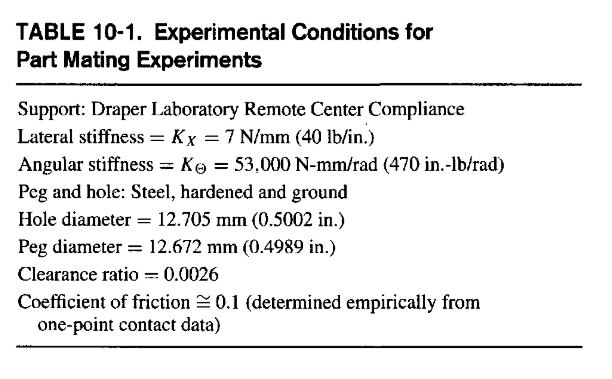

%Parameters to change

K_x = 7             % Spring lateral stiffness

K_x = 7

K_theta = 53000     % Spring angular stiffness

K_theta = 53000

D = 12.705          % Diameter of hole

D = 12.7050

R = D/2             % Radius of hole

R = 6.3525

C = 0.0026          % Clearance ratio

C = 0.0026

d = D-(C*D)         % Diameter of peg

d = 12.6720

r = d/2             % Radius of peg     

r = 6.3360

mu = 0.1            % Coefficient of friction

mu = 0.1000

ep_0 = 0.83         % Relative lateral error

ep_0 = 0.8300

L_g = 45            % Compliance centre from tip of peg (if l_g is closed to 0, use mu*r instead)

L_g = 45

theta_0 = 0.000     % Relative angular error

theta_0 = 0

alpha = deg2rad(45) % Alpha in degrees

alpha = 0.7854

W = ep_0*1.2        % Width of chamfer (assuming chamfer is bigger than relative lateral error

W = 0.9960

### Calculation example

**Check if peg hits chamfer using |ep_0| < W**

-     if yes, continue. If no, insertion miss chamfer & hole.

abs(ep_0)

ans = 0.8300

W

W = 0.9960

if abs(ep_0) < W
    fprintf('insertion possible, continue')
else
    fprintf('insertion miss chamfer and hole')
end

insertion possible, continue

**Check if wedging occurs using theta_0 < sqrt(2*c) & **$|\theta_0 + S \epsilon_0| <  \pm c/\mu$

-     if yes, continue. If no, insertion will wedge.

theta_0

theta_0 = 0

sqrt(2*c(D,d))

ans = 0.0721

abs(theta_0 + S(K_x,L_g, K_theta)*ep_0)

ans = 0.0039

c(D,d)/mu

ans = 0.0260


if theta_0 < sqrt(2*c(D,d)) && abs(theta_0 + S(K_x,L_g, K_theta)*ep_0) < c(D,d)/mu
    fprintf('insertion possible, continue')
else
    fprintf('insertion will wedge')
end

insertion possible, continue

**Find location when peg hits chamfer (z), 2 point contact starts (l_2), 2 point contact ends (l_2p)**

c1 = c(D,d);
ep_0p1 = ep_0p(ep_0, c1, R);
z1 = -z(ep_0p1,alpha) 

z1 = -0.8135


ep_0pp1 = ep_0pp(ep_0, c1, R);

AA = (K_x * L_g^2) + K_theta

AA = 67175

AL = K_x * (ep_0pp1 + (L_g *theta_0)) %alpha

AL = 5.9256

BE = (AL * L_g) + (K_x * L_g * C * D) - (AL * mu * D / 2) + (K_theta * theta_0) %beta

BE = 273.2938

GA = (AA - (K_x * L_g * mu * D / 2)) * C *D %gamma

GA = 2.2124e+03


l_21 = (BE - sqrt(BE^2 - (4 * AL * GA)))/ (2 * AL) 

l_21 = 10.4738

l_2p1 = (BE + sqrt(BE^2 - (4 * AL * GA)))/ (2 * AL)

l_2p1 = 35.6470

%if sqrt is imaginary, it means that 2 point contact did not occur

theta_l21 = theta_l2(l_21, c1, D)

theta_l21 = 0.0032

theta_l2p1 = theta_l2p(l_2p1, c1, D)

theta_l2p1 = 9.2667e-04

**Chamfer Crossing: For l = -z to 0**

***One may assume that chamfer crossing force and angle each increase linearly during chamfer crossing, with force starting at zero and 9 starting at 00***

A1 = A(alpha,mu)

A1 = 0.7778

B1 = B(alpha,mu)

B1 = 0.6364

D1 = DD(K_x, L_g, K_theta)

D1 = 67175

E1 = E(K_x, L_g, r, A1)

E1 = 1.5524e+03


Fz = 0;
theta_m = theta_0;
U = U_0(ep_0,L_g,theta_0);
Fx = 0;

for i = z1 %i is taken as -i due to the sign convention of z 
    Fz =        [ Fz ; F_z_c(K_x, K_theta, A1, -z1, alpha, B1, D1, E1)];
    Fx =        [ Fx ; F_x_c(K_theta, K_x, -z1, alpha, L_g, A1, B1, r) ];
    theta_m =   [ theta_m ; theta_cross(theta_0, K_theta, K_x, -z1, alpha, L_g, A1, B1, r)];
    U =         [ U ; U_cross(U_0(ep_0,L_g,theta_0), K_theta, K_x, -z1, alpha, L_g, A1, B1, r)];
end
Fz

Fz =          0
    5.6981


Fx

Fx =          0
   -4.6621


theta_m

theta_m =          0
    0.0033


U

U =     0.8300
    0.1640


**Check for 2-point contact: **

Check if * (beta^2 < 4*alpa*gamma), there will be no 2-point contact - proceed to remain as 1 contact point*

BE^2

ans = 7.4690e+04

4*AL*GA

ans = 5.2439e+04

if BE^2 < 4*AL*GA
    fprintf('no 2 point contact')
else
    fprintf('2 point contact detected')
end

2 point contact detected

**1 Point contact: For l = 0 to l_2**

for i = 0:0.1:l_21
    Fz =        [ Fz ; F_z_1(mu, K_x, K_theta, ep_0p1, i, theta_0, CC(K_x, L_g, i, mu, r), L_g) ];
    Fx =        [ Fx ; F_x_1(K_x, ep_0p1, i, theta_0, CC(K_x, L_g, i, mu, r), L_g, K_theta) ];
    theta_m =   [ theta_m ; theta_1(ep_0p1, CC(K_x, L_g, i, mu, r), L_g, theta_0, K_theta, i)];
    U =         [ U ; U_1(U_0(ep_0,L_g,theta_0), ep_0p1, i, theta_0, CC(K_x, L_g, i, mu, r), L_g, K_theta)];
end
Fz

Fz =          0
    5.6981
    0.4506
    0.4510
    0.4515
    0.4519
    0.4523
    0.4527
    0.4531
    0.4536


Fx

Fx =          0
   -4.6621
   -4.5062
   -4.5104
   -4.5146
   -4.5188
   -4.5230
   -4.5272
   -4.5314
   -4.5356


theta_m

theta_m =          0
    0.0033
    0.0038
    0.0038
    0.0038
    0.0038
    0.0038
    0.0037
    0.0037
    0.0037


U

U =     0.8300
    0.1640
    0.1863
    0.1857
    0.1851
    0.1845
    0.1839
    0.1833
    0.1827
    0.1821


**2 point contact:**

- For l = l_2 to L_g, beyond 2 point contact

F1 = F(K_x, L_g, ep_0pp1)

F1 = 266.6527

G1 = G(K_x, L_g)

G1 = -315


for i = (l_21):0.1:L_g
    Fz =        [ Fz ; F_z_2(mu, D1, D, theta_0, c1, i, F1, G1, d, L_g) ];
    Fx =        [ Fx ; F_x_2(K_x, L_g, theta_0, c1, D, i, ep_0pp1) ];
    U =         [ U ; U_2(U_0(ep_0,L_g,theta_0), ep_0pp1, L_g, theta_0, theta_2(i, c1, D))];
end
Fz

Fz =          0
    5.6981
    0.4506
    0.4510
    0.4515
    0.4519
    0.4523
    0.4527
    0.4531
    0.4536


Fx

Fx =          0
   -4.6621
   -4.5062
   -4.5104
   -4.5146
   -4.5188
   -4.5230
   -4.5272
   -4.5314
   -4.5356


U

U =     0.8300
    0.1640
    0.1863
    0.1857
    0.1851
    0.1845
    0.1839
    0.1833
    0.1827
    0.1821



for i = (l_21):0.1:l_2p1
    theta_m =   [ theta_m ; theta_2(i, c1, D)];
end

for i = l_2p1:0.1:L_g
    theta_m =   [ theta_m ; 0];
end
theta_m

theta_m =          0
    0.0033
    0.0038
    0.0038
    0.0038
    0.0038
    0.0038
    0.0037
    0.0037
    0.0037


**For no 2 point contact, remains as 1 point contact:**

- For l = 0 to L_g, 1 point contact

% for i = 0:0.1:L_g
%     Fz =        [ Fz ; F_z_1(mu, K_x, K_theta, ep_0p1, i, theta_0, CC(K_x, L_g, i, mu, r), L_g) ];
%     Fx =        [ Fx ; F_x_1(K_x, ep_0p1, i, theta_0, CC(K_x, L_g, i, mu, r), L_g, K_theta) ];
%     theta_m =   [ theta_m ; theta_1(ep_0p1, CC(K_x, L_g, i, mu, r), L_g, theta_0, K_theta, i)];
%     U =         [ U ; U_1(U_0(ep_0,L_g,theta_0), ep_0p1, i, theta_0, CC(K_x, L_g, i, mu, r), L_g, K_theta)];
% end
% Fz
% Fx
% theta_m
% U

### **Plot graph **

L = [(z1-0.2) z1 0:0.1:l_21 (l_21):0.1:L_g]

L =    -1.0135   -0.8135         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000


**l vs Fz**

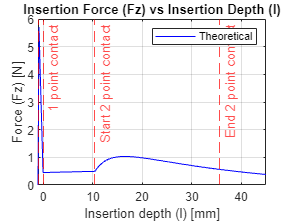

figure,
    plot (L,Fz, 'b')
    hold on
    chamferline = xline(z1, '--r', {'Chamfer contact'});
    chamferline.LabelHorizontalAlignment = 'left';
    pointline1 = xline(0, '--r', {'1 point contact'});
    pointline2 = xline(l_21, '--r', {'Start 2 point contact'});
    pointendline2 = xline(l_2p1 , '--r', {'End 2 point contact'});
    %pointmaxline2 = xline(Lmax , '--g', {'End 2 point contact'});
    grid on
    legend('Theoretical', 'Location','northeast')
    xlabel('Insertion depth (l) [mm]') 
    ylabel('Force (Fz) [N]')
    title ('Insertion Force (Fz) vs Insertion Depth (l)')

**l vs Fx**

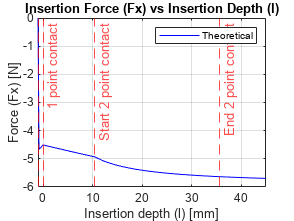

figure,
    plot (L,Fx, 'b')
    hold on
    chamferline = xline(z1, '--r', {'Chamfer contact'});
    chamferline.LabelHorizontalAlignment = 'left';
    pointline1 = xline(0, '--r', {'1 point contact'});
    pointline2 = xline(l_21, '--r', {'Start 2 point contact'});
    pointendline2 = xline(l_2p1 , '--r', {'End 2 point contact'});
    grid on
    legend('Theoretical', 'Location','northeast')
    xlabel('Insertion depth (l) [mm]') 
    ylabel('Force (Fx) [N]')
    title ('Insertion Force (Fx) vs Insertion Depth (l)')

**l vs U**

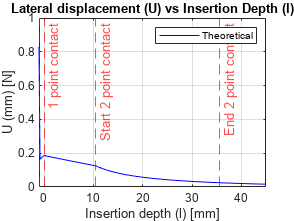

figure,
    plot (L,U, 'b')
    hold on
    chamferline = xline(z1, '--r', {'Chamfer contact'});
    chamferline.LabelHorizontalAlignment = 'left';
    pointline1 = xline(0, '--r', {'1 point contact'});
    pointline2 = xline(l_21, '--r', {'Start 2 point contact'});
    pointendline2 = xline(l_2p1 , '--r', {'End 2 point contact'});
    grid on
    legend('Theoretical', 'Location','northeast')
    xlabel('Insertion depth (l) [mm]') 
    ylabel('U (mm) [N]')
    title ('Lateral displacement (U) vs Insertion Depth (l)')

**theta vs l**

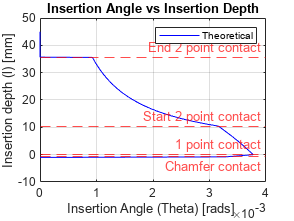

figure,
    plot (theta_m,L, 'b')
    hold on
    chamferline = yline(z1, '--r', {'Chamfer contact'});
    chamferline.LabelVerticalAlignment = 'bottom';
    yline(0, '--r', {'1 point contact'});
    yline(l_21, '--r', {'Start 2 point contact'});
    yline(l_2p1 , '--r', {'End 2 point contact'});
    grid on
    legend('Theoretical', 'Location','northeast')
    xlabel('Insertion Angle (Theta) [rads] ') 
    ylabel('Insertion depth (l) [mm]')
    title ('Insertion Angle vs Insertion Depth')